# Lecture 8 Application of Matlab in Numerical Analysis II: Root Findings

In this lecture, we will introduce two basic numerical methods to solve one-dimensional equation $f\left(x\right)=0$.

## Bisection Method

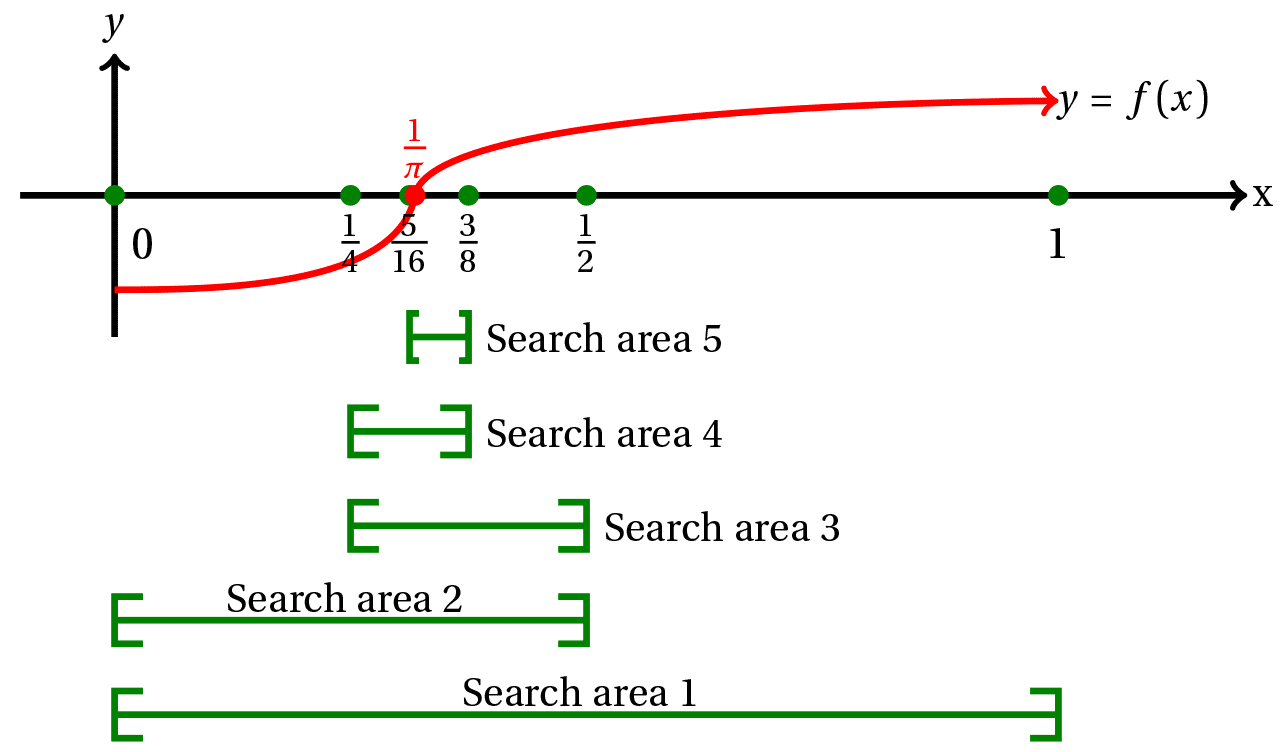

f = @(x) x.^2 -2;  % define function handle
bisection(f,0,2,1e-8)

ans = 1.4901e-08

ans = 1.4142

**Exercise**:

Modify the codes so that your function can do the followings:

1) display the message to user if the initial input of search inteveral does not satisfy requirement

2) add another input `l_thresh `to function, so that only when both the absolute function value is smaller than `f_thresh` and the length search interval is smaller than `l_thresh `will the program stop.

## Newton's Method


$$x_{k+1} =x_k -\frac{f\left(x_k \right)}{f^{\prime } \left(x_k \right)}$$


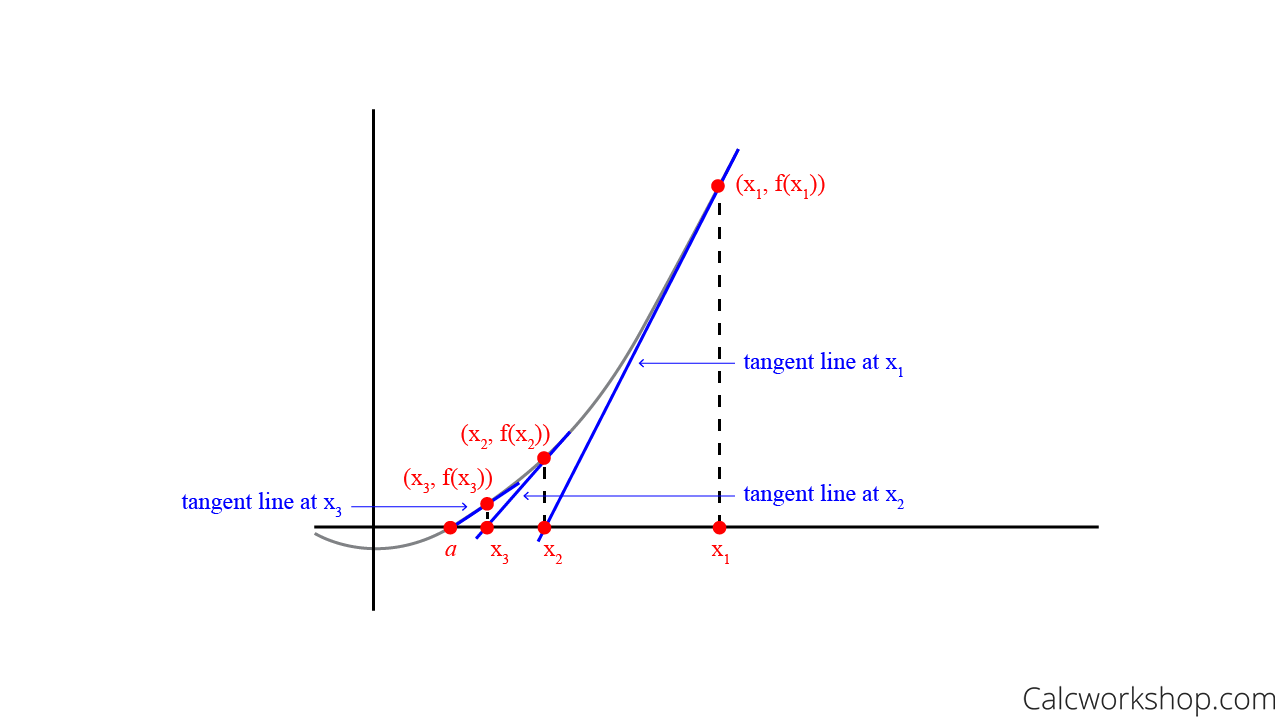

f = @(x) x.^2 -2;
g = @(x) 2*x;
newton(f,g,1,1e-6)

ans = 1.4142

f = @sin;
g = @cos;
newton(f,g,2,1e-6)

ans = 3.1416

**Exercise: **

Modify the codes so that your function can do the followings:

1) in addition to x, the function has another output denoting the total number of steps

2) try to avoid the input of derivative function by calculating the numerical derivatives in Newton's method. To be more specific, make step size h as the input to function and use central difference formula to approximate derivative in each step.

function x = bisection(f,a,b,f_thresh)
    
    c = (a+b)/2;
    
    while abs(f(c))>f_thresh
        if f(a)*f(c)<0
            b = c;
        else
            a = c;
        end
        c = (a+b)/2;
    end
    
    x = c;
end


function x = newton(f,g,x0,f_thresh)
    x = x0;
    while abs(f(x))>f_thresh
        x = x-f(x)/g(x);
    end

end
